# Import Data

In the below, **n** refers to the number of recording channels, **u** refers to the number of sorted units, and **k** refers to the number of samples.

chan_names：各电极标识名，格式：脑区 编号（如，M1 012）

finger_pos：受试猴子的手指实时位置

The position of the working fingertip in Cartesian coordinates **(z, -x, -y)**, as reported by the hand tracker in **cm**. 

t：finger_pos的采样时间戳，单位：s

spikes：每个电极（可能对应不止一个神经元）记录到的神经元放电时间序列，这里的数据已经预先做好了spike sorting，单位：s

其余数据项与本次实验关系不大

实验主要目的：建立回归模型，用神经放电数据预测手指运动轨迹和参数

load('.\indy_20160921_01.mat')

# 基本任务1

已有研究发现，M1运动编码采取population coding方式，多个神经元通过调谐曲线协同编码手部运动各参数（Georgopoulos 1986）。

选取一组数据，采用线性回归方法（或其他合理方法），通过M1发放率，设计模型，解码运动。

发放率计算：时间窗宽度64ms分bin，舍弃平均发放率小于0.5Hz的神经元

运动分解：在相同时间窗尺度上，计算每个时间窗的x，y方向的位移、速度、加速度（Position, Velocity, Acceleration）

要将数据切分为train, val (if necessary), test，性能评价指标使用测试集上的R^2和信噪比SNR

R^2计算参考[决定系数（R 方） - MATLAB & Simulink](https://ww2.mathworks.cn/help/stats/coefficient-of-determination-r-squared.html)


$$\textrm{SNR}=-10\;\log_{10} \left(1-R^2 \right)$$


## 发放率计算

w=0.064s

分bin

unit_spike = reshape(spikes, 1, []);
w = 0.064; % in second
[firing_rates, valid_units, bin_centers] = calculate_firing_rates(unit_spike, t, w); % instant firing rate
filtered_firing_rates = firing_rates(:, valid_units); % filter out those mean rate < 0.5 Hz

% figure;
% plot(bin_centers, firing_rates(:, 1));
% xlabel('time (s)');
% ylabel('firing rate (Hz)');
% title(sprintf('Firing rate of unit 1'));

## 运动分解

[position, velocity, acceleration, kinematics_time] = calculate_kinematics(finger_pos, t, bin_centers);

% figure;
% plot(t(72000:73000),-finger_pos(72000:73000,2))
% figure;
% plot(kinematics_time(4500:4560),position(4500:4560,1));
% figure;
% plot(kinematics_time(4500:4560),velocity(4500:4560,1));
% figure;
% plot(kinematics_time(4500:4560),acceleration(4500:4560,1));

## 分割数据集

train, test

split_ratio = [0.8, 0.2];
split_ratio = split_ratio / sum(split_ratio);

num_samples = size(filtered_firing_rates, 1);
num_train = round(num_samples * split_ratio(1));

idx = 1:num_samples;

train_idx = idx(1:num_train);
test_idx = idx(num_train+1:end);

train_firing_rates = filtered_firing_rates(train_idx, :);
train_position = position(train_idx, :);
train_velocity = velocity(train_idx, :);
train_acceleration = acceleration(train_idx, :);

test_firing_rates = filtered_firing_rates(test_idx, :);
test_position = position(test_idx, :);
test_velocity = velocity(test_idx, :);
test_acceleration = acceleration(test_idx, :);

## 线性回归

V=RA*

R'V=R'RA*

A*=(R'R)^-1 R'V

decoder_p_linear = (train_firing_rates' * train_firing_rates) \ (train_firing_rates' * train_position);
decoder_v_linear = (train_firing_rates' * train_firing_rates) \ (train_firing_rates' * train_velocity);
decoder_a_linear = (train_firing_rates' * train_firing_rates) \ (train_firing_rates' * train_acceleration);

## 性能评价

[r2_p, snr_p, predicted_p] = evaluate_decoder_linear(test_firing_rates, test_position, decoder_p_linear);
[r2_v, snr_v, predicted_v] = evaluate_decoder_linear(test_firing_rates, test_velocity, decoder_v_linear);
[r2_a, snr_a, predicted_a] = evaluate_decoder_linear(test_firing_rates, test_acceleration, decoder_a_linear);

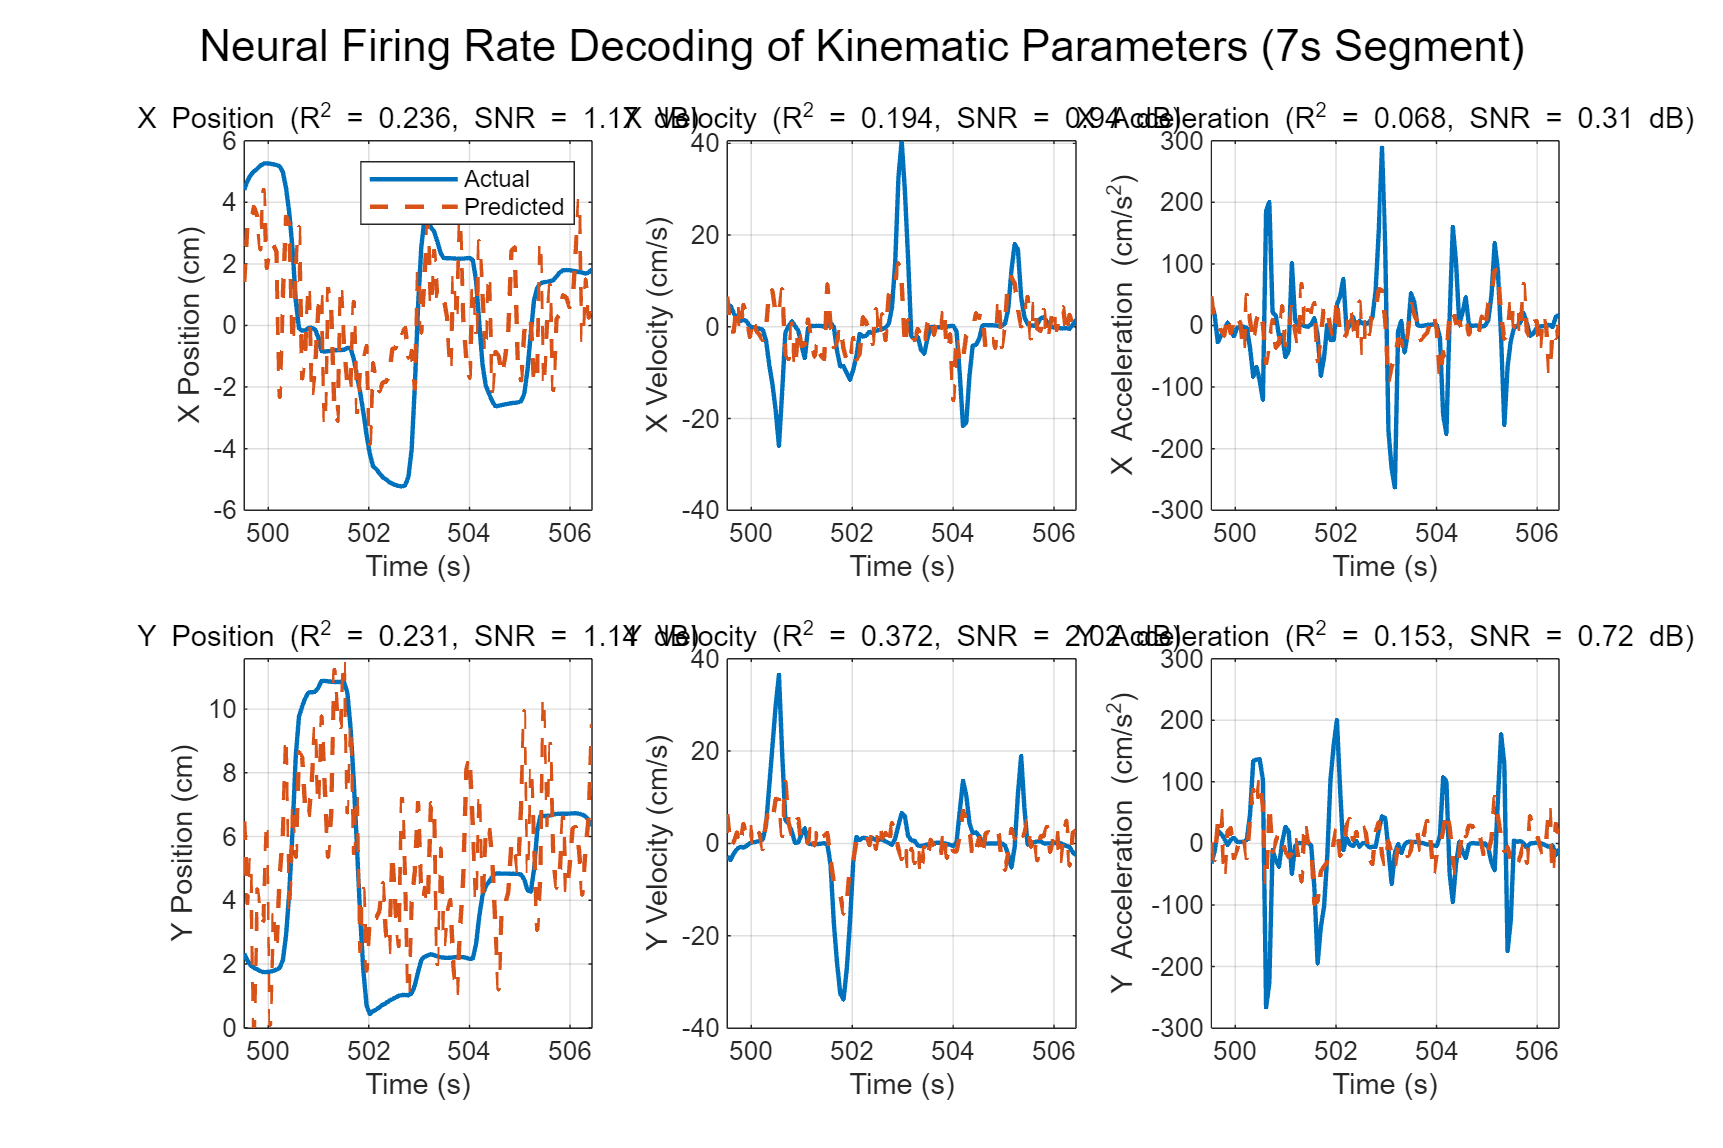

test_time = kinematics_time(test_idx);

% Select middle 7s of the data
total_time_span = test_time(end) - test_time(1);
middle_time = test_time(1) + total_time_span/2;
time_window = 7;
middle_indices = find(test_time >= (middle_time - time_window/2) & test_time <= (middle_time + time_window/2));

% Create a 2×3 subplot arrangement
figure('Position', [100 100 1200 800]);

% Position X
subplot(2,3,1);
plot(test_time(middle_indices), test_position(middle_indices,1), 'LineWidth', 1.5, 'DisplayName', 'Actual');
hold on;
plot(test_time(middle_indices), predicted_p(middle_indices,1), '--', 'LineWidth', 1.5, 'DisplayName', 'Predicted');
title(sprintf('X Position (R^2 = %.3f, SNR = %.2f dB)', r2_p(1), snr_p(1)));
xlabel('Time (s)');
ylabel('X Position (cm)');
legend('Location', 'northeast');
grid on;

% Velocity X
subplot(2,3,2);
plot(test_time(middle_indices), test_velocity(middle_indices,1), 'LineWidth', 1.5, 'DisplayName', 'Actual Velocity');
hold on;
plot(test_time(middle_indices), predicted_v(middle_indices,1), '--', 'LineWidth', 1.5, 'DisplayName', 'Predicted Velocity');
title(sprintf('X Velocity (R^2 = %.3f, SNR = %.2f dB)', r2_v(1), snr_v(1)));
xlabel('Time (s)');
ylabel('X Velocity (cm/s)');
grid on;

% Acceleration X
subplot(2,3,3);
plot(test_time(middle_indices), test_acceleration(middle_indices,1), 'LineWidth', 1.5, 'DisplayName', 'Actual Acceleration');
hold on;
plot(test_time(middle_indices), predicted_a(middle_indices,1), '--', 'LineWidth', 1.5, 'DisplayName', 'Predicted Acceleration');
title(sprintf('X Acceleration (R^2 = %.3f, SNR = %.2f dB)', r2_a(1), snr_a(1)));
xlabel('Time (s)');
ylabel('X Acceleration (cm/s^2)');
grid on;

% Position Y
subplot(2,3,4);
plot(test_time(middle_indices), test_position(middle_indices,2), 'LineWidth', 1.5, 'DisplayName', 'Actual Position');
hold on;
plot(test_time(middle_indices), predicted_p(middle_indices,2), '--', 'LineWidth', 1.5, 'DisplayName', 'Predicted Position');
title(sprintf('Y Position (R^2 = %.3f, SNR = %.2f dB)', r2_p(2), snr_p(2)));
xlabel('Time (s)');
ylabel('Y Position (cm)');
grid on;

% Velocity Y
subplot(2,3,5);
plot(test_time(middle_indices), test_velocity(middle_indices,2), 'LineWidth', 1.5, 'DisplayName', 'Actual Velocity');
hold on;
plot(test_time(middle_indices), predicted_v(middle_indices,2), '--', 'LineWidth', 1.5, 'DisplayName', 'Predicted Velocity');
title(sprintf('Y Velocity (R^2 = %.3f, SNR = %.2f dB)', r2_v(2), snr_v(2)));
xlabel('Time (s)');
ylabel('Y Velocity (cm/s)');
grid on;

% Acceleration Y
subplot(2,3,6);
plot(test_time(middle_indices), test_acceleration(middle_indices,2), 'LineWidth', 1.5, 'DisplayName', 'Actual Acceleration');
hold on;
plot(test_time(middle_indices), predicted_a(middle_indices,2), '--', 'LineWidth', 1.5, 'DisplayName', 'Predicted Acceleration');
title(sprintf('Y Acceleration (R^2 = %.3f, SNR = %.2f dB)', r2_a(2), snr_a(2)));
xlabel('Time (s)');
ylabel('Y Acceleration (cm/s^2)');
grid on;

% Add overall title
sgtitle('Neural Firing Rate Decoding of Kinematic Parameters (7s Segment)');

# 基础任务2

M1神经元对速度方向存在cos调谐规律。

试通过一些简单方法挑选出对velocity贡献较大的神经元，画出其中10个典型的M1神经元对于不同速度方向相应的直方图，用余弦函数近似，作为其调谐曲线，得到偏好角度

y = a cos(x+theta) + b

将挑选出来的所有神经元的偏好角度画在单位圆上

## 挑选unit

重要性阈值80，即前20%神经元被视为“重要”

threshold_percentile = 80;

decoder = decoder_v_linear;

% 用L2范数衡量重要程度
neuron_importance = sqrt(sum(decoder.^2, 2));

importance_threshold = prctile(neuron_importance, threshold_percentile);
important_neuron_indices = find(neuron_importance >= importance_threshold);
important_neurons_count = length(important_neuron_indices);

## 前10个units、速度分bin

[sorted_importance, sorted_indices] = sort(neuron_importance, 'descend');
num_to_plot = min(10, length(sorted_indices));

% 计算速度方向角度(0-360度)
velocity_angles = atan2d(velocity(:, 2), velocity(:, 1)); % [-180, 180]
velocity_angles(velocity_angles < 0) = velocity_angles(velocity_angles < 0) + 360;

% 将360°分为36个bin，每个bin 10°
angle_bins = 0:10:360;
num_bins = length(angle_bins) - 1;
bin_centers = (angle_bins(1:end-1) + angle_bins(2:end)) / 2;

% 为静止窗口创建掩码(速度接近0的时间点)
speed = sqrt(sum(velocity.^2, 2));
movement_mask = speed > 0.01; % 0.01 cm/s作为运动阈值
valid_samples = find(movement_mask);
valid_angles = velocity_angles(valid_samples);

## 余弦拟合、绘图

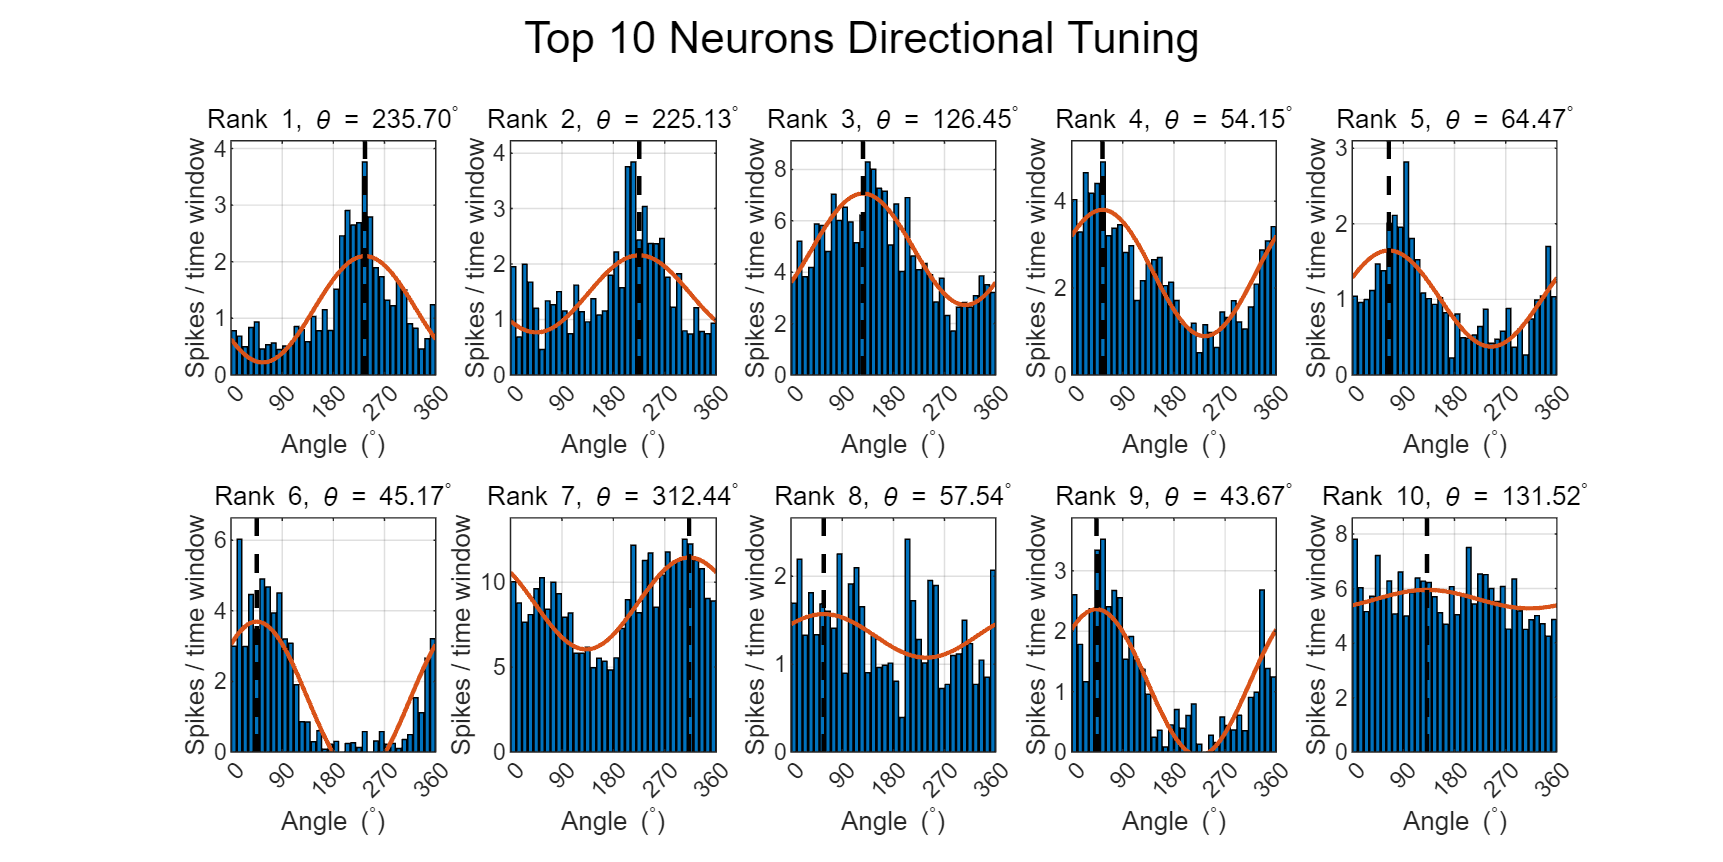

fit_func = @(params, x) params(1) .* cosd(x + params(2)) + params(3);

figure('Position', [100, 100, 1200, 600]);

for i = 1:num_to_plot
    neuron_idx = sorted_indices(i);
    neuron_firing_rate = filtered_firing_rates(:, neuron_idx);
    valid_rates = neuron_firing_rate(valid_samples);
    subplot(2, 5, i);
    
    mean_rates = zeros(num_bins, 1);
    
    for bin = 1:num_bins
        % 找出落在当前角度bin且有运动的时间点
        bin_mask = velocity_angles >= angle_bins(bin) & velocity_angles < angle_bins(bin+1) & movement_mask;
        
        if any(bin_mask)
            mean_rates(bin) = mean(neuron_firing_rate(bin_mask));
        end
    end
    
    bar(bin_centers, mean_rates);
    h_bar.FaceAlpha = 0.6; % 透明度
    hold on;

    % fit cos
    initial_params = [1, 0, mean(valid_rates)];

    % 尝试多个初始参数，选择最佳拟合
    best_cost = Inf;
    best_params = initial_params;
    
    for phase_start = 0:45:315  % 尝试不同的初始相位
        test_params = [1, phase_start, mean(valid_rates)];
        cost_func = @(params) sum((fit_func(params, valid_angles) - valid_rates).^2);
        
        try
            [fitted_params, cost] = fminsearch(cost_func, test_params, optimset('Display', 'off'));
            
            if cost < best_cost
                best_cost = cost;
                best_params = fitted_params;
            end
        catch
            continue;
        end
    end
    
    fitted_params = best_params;

    % get fit params
    a = fitted_params(1);
    theta = mod(fitted_params(2), 360); % 0~360
    b = fitted_params(3);

    x_fit = 0:1:360;
    y_fit = fit_func(fitted_params, x_fit);

    plot(x_fit, y_fit, 'LineWidth', 1.5);

    % get preferred dir
    if a > 0
        pd = mod(360 - theta, 360);
    else
        pd = mod(540 - theta, 360);
    end

    y_max = max(mean_rates);
    y_min = min([0; mean_rates]);
    y_range = [y_min, y_max + 0.1*(y_max-y_min)];

    plot([pd, pd], y_range, 'k--', 'LineWidth', 1.5);
    
    title(sprintf('Rank %d, \\theta = %.2f^{\\circ}', i, pd));
    xlabel('Angle (^{\circ})');
    ylabel('Spikes / time window');
    xlim([0, 360]);
    ylim(y_range);
    set(gca, 'XTick', 0:90:360);
    grid on;
    hold off;
end

sgtitle('Top 10 Neurons Directional Tuning');

## 单位圆

pds = zeros(important_neurons_count, 1);

for i = 1:important_neurons_count
    neuron_idx = important_neuron_indices(i);
    neuron_firing_rate = filtered_firing_rates(:, neuron_idx);
    valid_rates = neuron_firing_rate(valid_samples);
    mean_rates = zeros(num_bins, 1);
    
    for bin = 1:num_bins
        % 找出落在当前角度bin且有运动的时间点
        bin_mask = velocity_angles >= angle_bins(bin) & velocity_angles < angle_bins(bin+1) & movement_mask;
        
        if any(bin_mask)
            mean_rates(bin) = mean(neuron_firing_rate(bin_mask));
        end
    end
    
    % fit cos
    initial_params = [1, 0, mean(valid_rates)];
    
    % 尝试多个初始参数，选择最佳拟合
    best_cost = Inf;
    best_params = initial_params;
    
    for phase_start = 0:45:315  % 尝试不同的初始相位
        test_params = [1, phase_start, mean(valid_rates)];
        cost_func = @(params) sum((fit_func(params, valid_angles) - valid_rates).^2);
        
        try
            [fitted_params, cost] = fminsearch(cost_func, test_params, optimset('Display', 'off'));
            
            if cost < best_cost
                best_cost = cost;
                best_params = fitted_params;
            end
        catch
            continue;
        end
    end
    
    fitted_params = best_params;

    % get fit params
    a = fitted_params(1);
    theta = mod(fitted_params(2), 360); % 0~360

    % get preferred dir
    if a > 0
        pd = mod(360 - theta, 360);
    else
        pd = mod(540 - theta, 360);
    end
    pds(i) = pd;
end

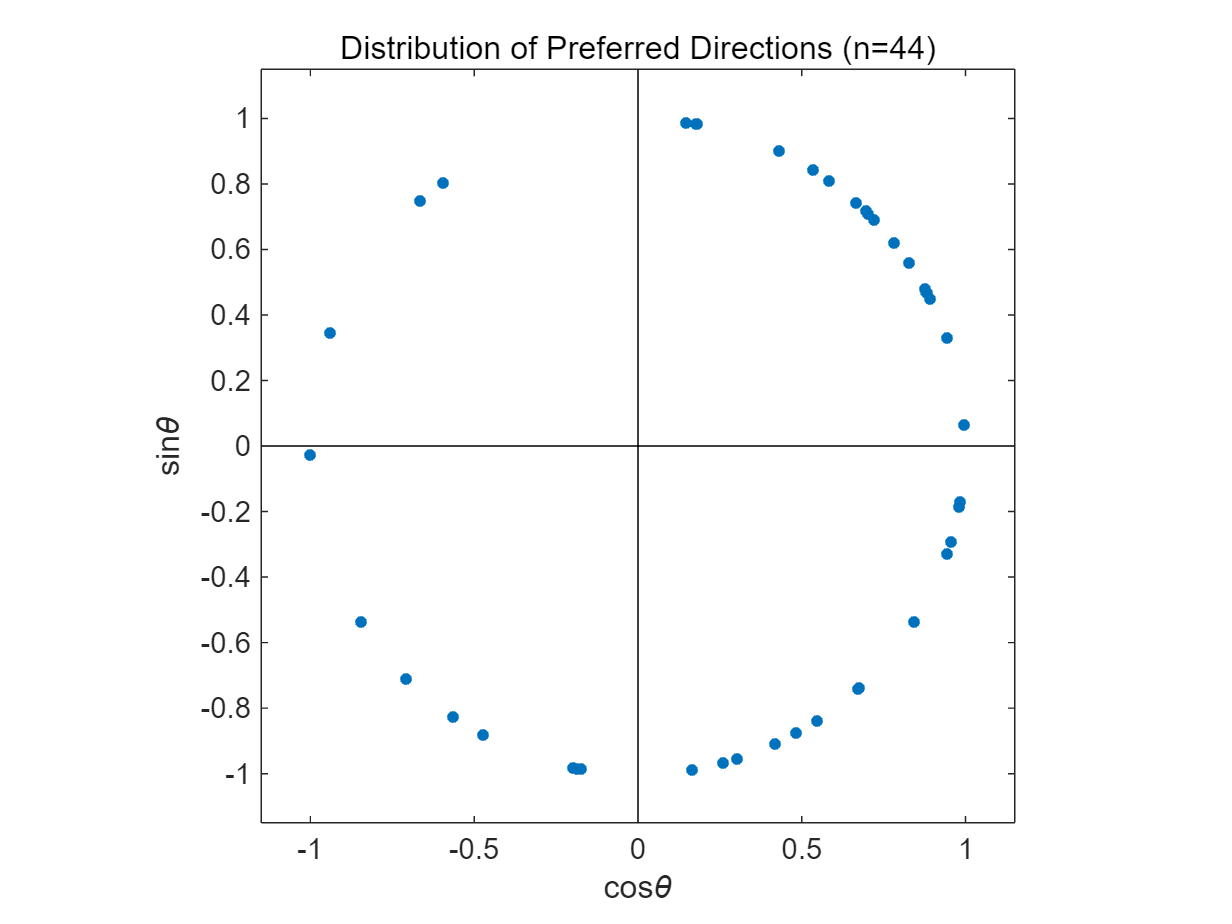

pdx = cosd(pds);
pdy = sind(pds);

figure;
plot(pdx, pdy, '.', MarkerSize=12);
hold on;
plot([-1.15 1.15], [0 0], 'k-');
plot([0 0], [-1.15 1.15], 'k-');
xlim([-1.15, 1.15]);
ylim([-1.15, 1.15]);
axis square;
xlabel('cos\theta');
ylabel('sin\theta');
title(sprintf('Distribution of Preferred Directions (n=%d)', important_neurons_count));
hold off;